# DSOGI-PLL

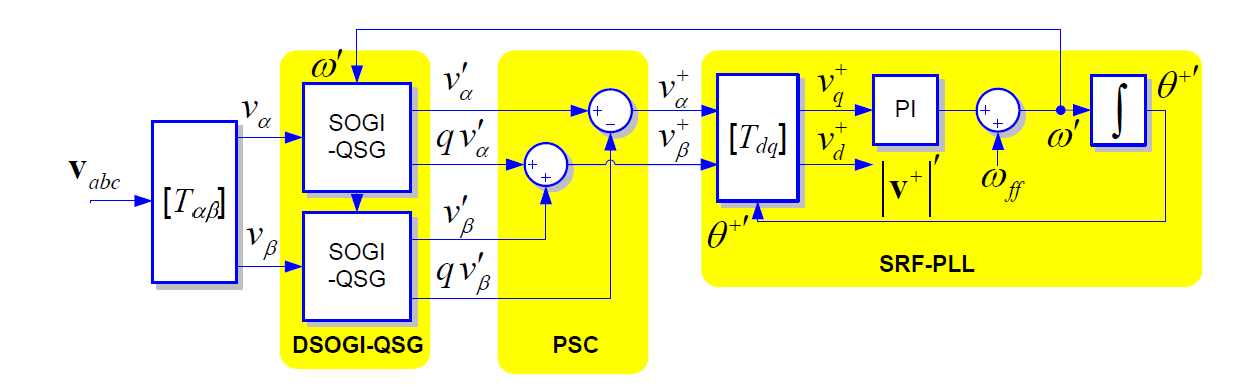

[1] Pinto J, Carvalho A, Rocha A, Araújo A. Comparison of DSOGI-Based PLL for Phase Estimation in Three-Phase Weak Grids. *Electricity*. 2021; 2(3):244-270. [https://doi.org/10.3390/electricity2030015](https://doi.org/10.3390/electricity2030015)

**SOGI**

%                   k*wolp*s            
%   D(s) =  -------------------------   
%             s*s+k*wolp*s+wolp*wolp                  

%                   k*wolp*wolp
%   Q(s) =  -------------------------
%               s*s+k*wolp*s+wolp*wolp

k_sogi1=.5;
wolp=50*2*pi;
tsample=1/10e3;
d_s = tf([k_sogi1*wolp 0],[1 k_sogi1*wolp wolp*wolp]);
q_s = tf(k_sogi1*wolp*wolp,[1 k_sogi1*wolp wolp*wolp]);
d_z=c2d(d_s,tsample,'tustin')

d_z =
 
  0.007791 z^2 - 0.007791
  -----------------------
  z^2 - 1.983 z + 0.9844
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


q_z=c2d(q_s,tsample,'tustin')

q_z =
 
  0.0001224 z^2 + 0.0002448 z + 0.0001224
  ---------------------------------------
          z^2 - 1.983 z + 0.9844
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


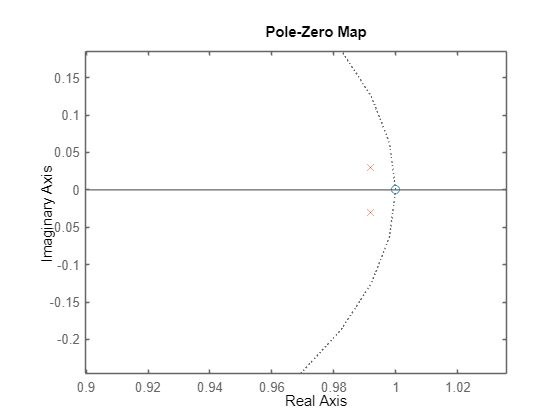


close all
figure(1)
bpo=bodeoptions;
bpo.FreqUnits = 'Hz'; 
h = pzplot(d_z,q_z); 
p = getoptions(h);
p.XLim = {[0.899622, 1.03599]};
p.YLim = {[-0.246123, 0.185639]};
setoptions(h,p);

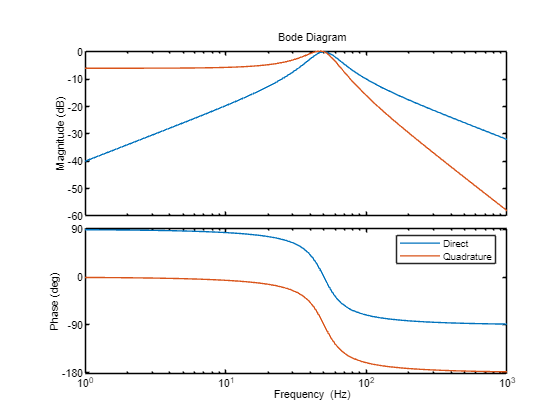

bodeplot(d_s,q_s,bpo)
legend('Direct','Quadrature');

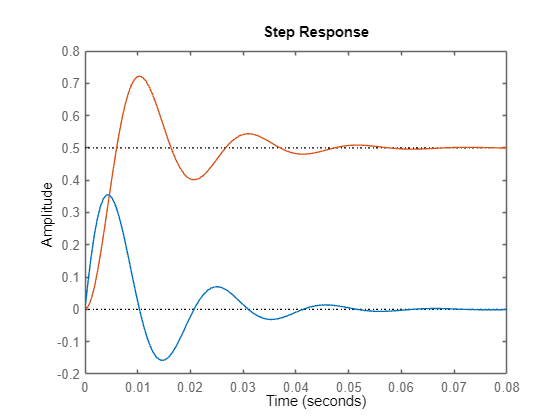

step(d_s,q_s)

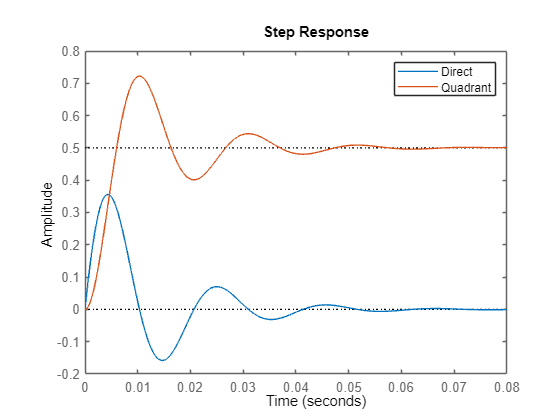

step(d_z,q_z)
legend('Direct','Quadrant')

**PI Controller Parallel**

%               kp*s+ki                 2*wn*sig           Vac_peak
%  PI(s) =  -----------------   Kp= --------------    Ki=-------------
%                  s                    Vac_peak            4*sig*sig
% 
wn_pi=80*2*pi;%200*2*pi; 
sig_pi=.001;%.05;
vac_peak_pi=10*3.3/1;
kp =2*wn_pi*sig_pi/vac_peak_pi;
ki = vac_peak_pi/(4*sig_pi*sig_pi);
pi_s=tf([kp ki],[1 0]);
pi_z=c2d(pi_s,tsample,'zoh')

pi_z =
 
  0.03046 z + 825
  ---------------
       z - 1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


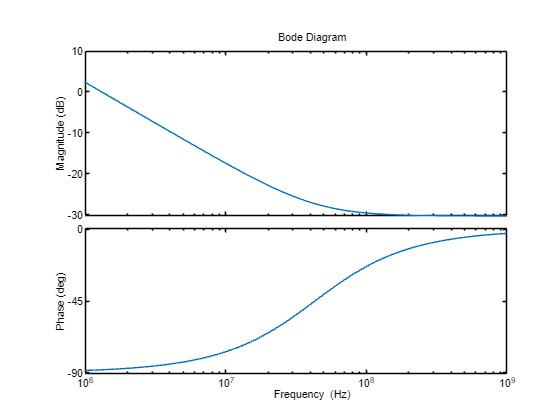

% close all
bpo=bodeoptions;
bpo.FreqUnits = 'Hz';
bodeplot(pi_s,bpo);

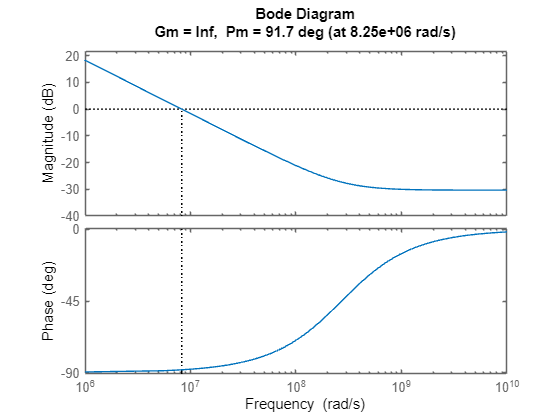


margin(pi_s)

% pi_cl=feedback(pi_s,1);
% stepinfo(pi_cl)
% bodeplot(pi_z,bpo)
% pi_z_cl=feedback(pi_z,1);
% pzmap(pi_z_cl)

**LPF Feedback w_est**

%                      Kg*wn*wn
%   LPF(s) =  -------------------------       sig>1 wn=?
%               s*s+2*sig*wn*s+wn*wn
% sig=2.5;
% wn=2*pi*100;
% Kg=1.2;
% lpf_s = tf(Kg*wn*wn,[1 2*sig*wn wn*wn]);
% lpf_z = c2d(lpf_s,tsample,'tustin');
% close all
% figure(3)
% bpo=bodeoptions;
% bpo.FreqUnits = 'Hz'; 
% bodeplot(lpf_z,bpo)
% bodeplot(lpf_s,bpo);
% step(lpf_z)
% stepinfo(lpf_s)

**Simulation**

fs=10e3;ts=1/fs;tsim=14/50;t=0:ts:tsim; % inputs range ¿0~3.3|5.5? ¿gain? ¿vline/vout? %I'll consider 3.3v->350vpk


- Input Waveform

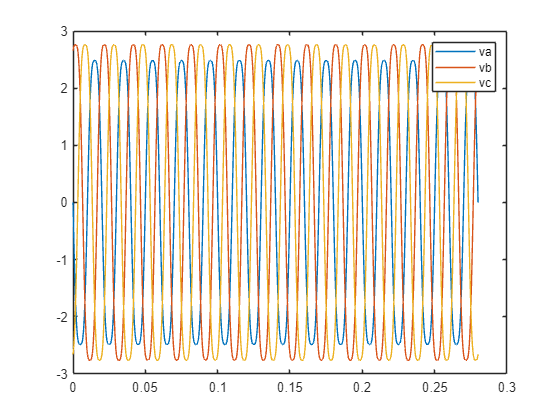

% Analysis done for in btw 65 & 45Hz .  
% start ang offset: pi. voltage unbalance 10% in one phase. 3rd harmonic 10% amplitud

vamp=3.3*sqrt(2)*230/350;
w_in=2*pi*50; %input angular frequency
off_angle=pi;%worst case
va=(vamp*.9*((sin(w_in*t+off_angle)+.1*sin(3*(w_in*t+off_angle)))));
vb=(vamp*((sin(w_in*t-(2*pi/3)+off_angle)+.1*sin(3*(w_in*t-(2*pi/3)+off_angle)))));   %phase shift 10% why matlab 4pi/3->120???
vc=(vamp*((sin(w_in*t-(4*pi/3)+off_angle))+.1*sin(3*(w_in*t-(4*pi/3)+off_angle)))); %voltage dump %10 w phase shift 10%

plot(t,va,t,vb,t,vc)
legend('va','vb','vc')

- Clark Transform

% v_ct_alpha(k)=(2/3)*(va(k)-.5*vb(k)-.5*vc(k));
% v_ct_betha(k)=(2/3)*(sqrt(3)*.5)*(vb(k)-vc(k));
% plot(t,v_ct_alpha,t,v_ct_betha)
% legend('v_ct_alpha','v_ct_betha')
v_ct_alpha=(zeros(length(t),1));
v_ct_betha=(zeros(length(t),1));

- LPF

% w_lpf(k)=( ( lpf_n1*(w_est(k)+w_est(k-2))+(lpf_n2*w_est(k-1)) )-(lpf_d1*w_lpf(k-1))-(lpf_d2*w_lpf(k-2)) )/lpf_d0;
wnn=(2*pi*50);
% lpf_n1=Kg*wn*wn;
% lpf_n2=Kg*2*wn*wn;
% lpf_d2=(4*fs*fs)-(2*sig*wn*fs)+(wn*wn);
% lpf_d1=((2*wn*wn)-(8*fs*fs));
% lpf_d0=(4*fs*fs)+(2*sig*wn*fs)+(wn*wn);

w_est=(zeros(length(t),1));w_est(1)=wnn;w_est(2)=wnn;w_est(3)=wnn;
w_lpf=(zeros(length(t),1));w_lpf(1)=wnn;w_lpf(2)=wnn;w_lpf(3)=wnn;

- Sogi

% vd_sogi(k)= ( d_sogi_n1*(v_(k)-v_(k-2))-(vd_sogi(k-1)*d_sogi_d2)-(vd_sogi(k-2)*d_sogi_d1) )/d_sogi_d3;d_sogi_n1 =( k_sogi1*wolp);
d_sogi_d1 =( (2/ts)-(k_sogi1*wolp)+(ts*.5*wolp*wolp));
d_sogi_d2 =( (ts*wolp*wolp)-(4*fs));
d_sogi_d3 =( (2/ts)+(k_sogi1*wolp)+(ts*.5*wolp*wolp)) ;

vd_sogi_alpha=(zeros(length(t),1));
vd_sogi_betha=(zeros(length(t),1));

% vq_sogi(k)=(  ( q_sogi_n1*( v_(k-2)+v_(k) )+( q_sogi_n2*v_(k-1) ) ) -( vq_sogi(k-2)*q_sogi_d2 )-( vq_sogi(k-1)*q_sogi_d1 )  )/q_sogi_d0;
q_sogi_n1=(k_sogi1*wolp*wolp);
q_sogi_n2=(k_sogi1*wolp*wolp*2);
q_sogi_d2=((4*fs*fs)-(2*fs*k_sogi1*wolp)+(wolp*wolp));
q_sogi_d1=((2*wolp*wolp)-(8*fs*fs));
q_sogi_d0=((4*fs*fs)+(2*fs*k_sogi1*wolp)+(wolp*wolp));

vq_sogi_alpha=zeros(length(t),1);
vq_sogi_betha=zeros(length(t),1);


- Park Transform

theta=zeros(length(t),1);theta(2)=0;
sin_th=zeros(length(t),1);cos_th=zeros(length(t),1);cos_th(2)=1;
% vq_park(k)=cos(theta(k))*vp_alpha(k)-sin(theta(k))*vp_betha(k);
vq_park=zeros(length(t),1);
vd_park=zeros(length(t),1);
vp_alpha=zeros(length(t),1);
vp_betha=zeros(length(t),1);

- PI controller

pi_n1=kp;
pi_n2=(ki*ts)-kp;
w_pi=zeros(length(t),1);
%w_pi(k)=vq_park(k)*pi_n1+vq_park(k-1)*pi_n2+w_pi(k-1);

for k=3:length(t)
    %Clark Transform
    v_ct_alpha(k)=((2/3)*(va(k)-.5*vb(k)-.5*vc(k)));
    v_ct_betha(k)=((2/3)*(sqrt(3)*.5)*(vb(k)-vc(k)));
    
    % %LPF
    % 
    w_lpf(k)=w_est(k-1);%( ( lpf_n1*(w_est(k)+w_est(k-2))+(lpf_n2*w_est(k-1)) )-(lpf_d1*w_lpf(k-1))-(lpf_d2*w_lpf(k-2)) )/lpf_d0;
    % 
    % %Dsogi
    d_sogi_n1 = (k_sogi1*w_lpf(k));
    d_sogi_d1 = ((2/ts)-(k_sogi1*w_lpf(k))+(ts*.5*w_lpf(k)*w_lpf(k)));
    d_sogi_d2 = ((ts*w_lpf(k)*w_lpf(k))-(4*fs));
    d_sogi_d3 = ((2/ts)+(k_sogi1*w_lpf(k))+(ts*.5*w_lpf(k)*w_lpf(k)));

    vd_sogi_alpha(k)=(( d_sogi_n1*(v_ct_alpha(k)-v_ct_alpha(k-2))-(vd_sogi_alpha(k-1)*d_sogi_d2)-(vd_sogi_alpha(k-2)*d_sogi_d1) )/d_sogi_d3);
    vd_sogi_betha(k)=( ( d_sogi_n1*(v_ct_betha(k)-v_ct_betha(k-2))-( vd_sogi_betha(k-1)*d_sogi_d2)-( vd_sogi_betha(k-2)*d_sogi_d1) )/d_sogi_d3);

    q_sogi_n1=(k_sogi1*w_lpf(k)*w_lpf(k));
    q_sogi_n2=(k_sogi1*w_lpf(k)*w_lpf(k)*2);
    q_sogi_d2=((4*fs*fs)-(2*fs*k_sogi1*w_lpf(k))+(w_lpf(k)*w_lpf(k)));
    q_sogi_d1=((2*w_lpf(k)*w_lpf(k))-(8*fs*fs));
    q_sogi_d0=((4*fs*fs)+(2*fs*k_sogi1*w_lpf(k))+(w_lpf(k)*w_lpf(k)));

    vq_sogi_alpha(k)=(((q_sogi_n1*(v_ct_alpha(k-2)+v_ct_alpha(k))+(q_sogi_n2*v_ct_alpha(k-1))) -(vq_sogi_alpha(k-2)*q_sogi_d2)-(vq_sogi_alpha(k-1)*q_sogi_d1))/q_sogi_d0);
    vq_sogi_betha(k)=(((q_sogi_n1*(v_ct_betha(k-2)+v_ct_betha(k))+(q_sogi_n2*v_ct_betha(k-1))) -(vq_sogi_betha(k-2)*q_sogi_d2)-(vq_sogi_betha(k-1)*q_sogi_d1))/q_sogi_d0);

    % %PSC
    vp_alpha(k)=(vd_sogi_alpha(k)-vq_sogi_betha(k));
    vp_betha(k)=(vq_sogi_alpha(k)+vd_sogi_betha(k));

    %SRF_Pll

    %Park Transform
    vq_park(k)=(sin_th(k-1)*vp_betha(k)+cos_th(k-1)*vp_alpha(k));%(-sin_th(k-1)*vp_alpha(k)+cos_th(k-1)*vp_betha(k));
    vd_park(k)=(sin_th(k-1)*vp_alpha(k)-cos_th(k-1)*vp_betha(k));
    
    % %PI controller
    w_pi(k)=((-0*vamp+vq_park(k))*pi_n1+(-0*vamp+vq_park(k-1))*pi_n2+w_pi(k-1));
    w_est(k)=wnn+w_pi(k);

    %DCO

    sin_th(k)=(sin_th(k-1)+(cos_th(k-1)*w_est(k)*ts));    %Sin(t+dt)=sin(t)+cos(t)*dt
    cos_th(k)=(cos_th(k-1)-(sin_th(k-1)*w_est(k)*ts));
    sin_th(k) = max([sin_th(k) -1]); 
    cos_th(k) = max([cos_th(k) -1]);
    sin_th(k) = min([sin_th(k) 1]);
    cos_th(k) = min([cos_th(k) 1]);  
    theta(k)=(theta(k-1)+w_est(k)*ts);
    if (sin_th(k-1))>=0 && sin_th(k)<=0
        theta(k)=-(pi); 
    end    

end

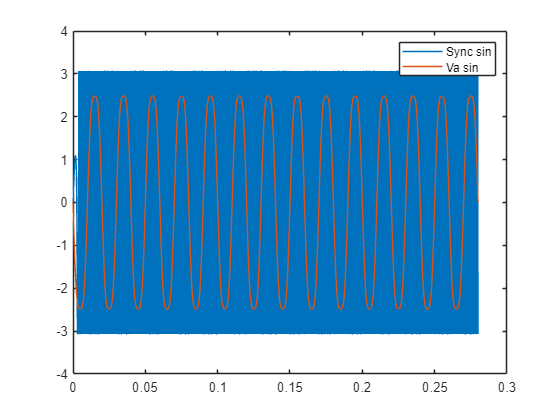

plot(t,vamp*sin_th,t,va)
legend('Sync sin','Va sin')

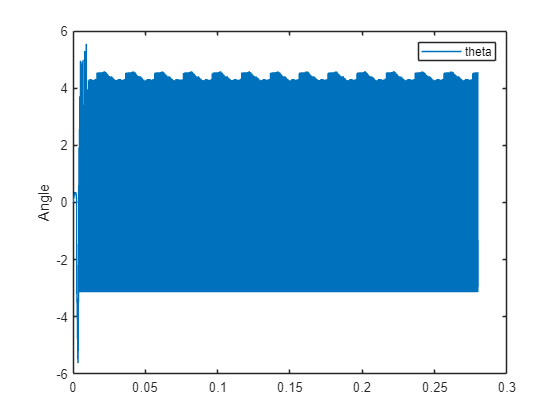

plot(t,theta)
ylabel('Angle')
legend('theta')

% pi2=2*pi;plot(t,w_lpf/pi2,t,w_pi/pi2,t,w_est/pi2)
% ylabel('Freq')
% legend('Freq_(lpf)','Freq_(pi)','Freq_(est)')
% plot(t,vq_park,t,vd_park)
% legend('Vq park','Vd park')
% 
% legend("Position", [0.71122,0.73722,0.16607,0.082143])

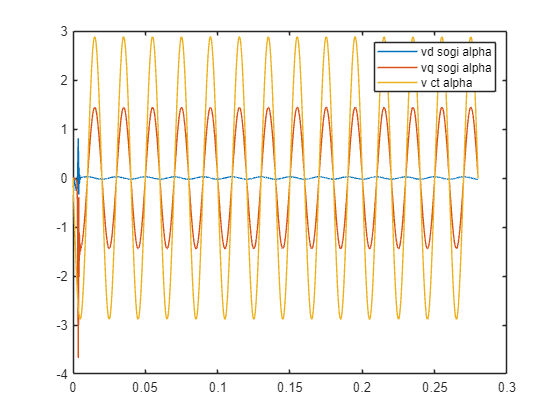

plot(t, vd_sogi_alpha,t, vq_sogi_alpha,t, v_ct_alpha)
legend('vd sogi alpha','vq sogi alpha','v ct alpha')

% plot(t, vd_sogi_betha,t, vq_sogi_betha,t, v_ct_betha)
% legend('vd sogi betha','vq sogi betha','v ct betha')
% plot(t, vp_alpha,t, vp_betha,t, v_ct_alpha,t, v_ct_betha)
% legend('Vp Alp','Vp Bet','v ct alpha','v ct betha')

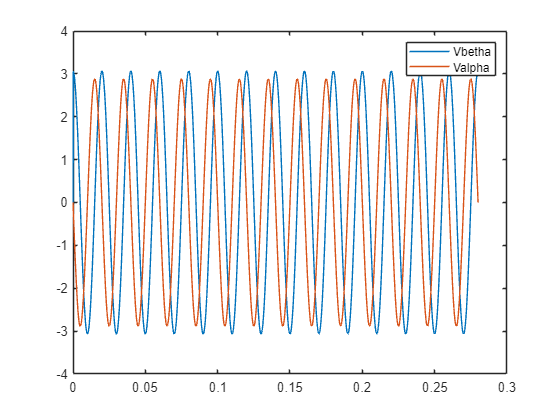

plot(t,v_ct_betha,t,v_ct_alpha )
legend('Vbetha','Valpha')

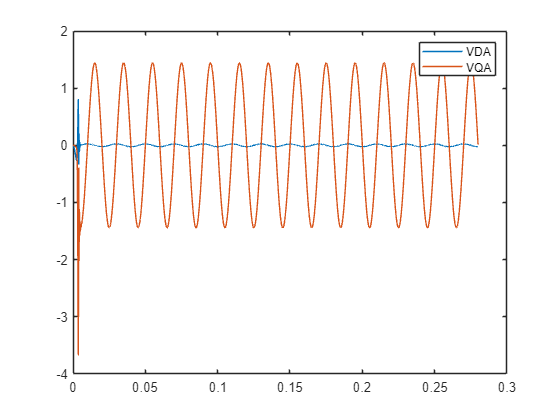

plot(t,vd_sogi_alpha,t,vq_sogi_alpha)
legend('VDA','VQA')

**A B C A B C **

**C B A C B A**

**A C B A C B**